%% MODELO TOE (Triple Oscilador Entrelazado) - SIMULACIÓN DINÁMICA
% Autor: Kilian Hernández Cabrera
% Simulación de la evolución temporal de la Fidelidad F(t)

clear; clc; close all;

%% 1. PARÁMETROS DEL SISTEMA
hbar = 1;               % Unidades naturales
g = 1.0;                % Acoplamiento entre qutrits de dirección
w1 = 1.0; w2 = 1.0; w3 = 1.0; % Frecuencias libres de los osciladores
n_max = 3;              % Truncamiento de Fock por oscilador (0, 1, ..., n_max)

% Dimensiones de los subespacios
dim_q = 3;              % Qutrit (x, y, z)
dim_osc = n_max + 1;    % Oscilador armónico
dim_single = dim_q * dim_osc; % Dimensión por fuente (12)
dim_total = dim_single^3;     % Dimensión total (1728)

fprintf('Dimensión total del espacio de Hilbert truncado: %d\n', dim_total);

Dimensión total del espacio de Hilbert truncado: 1728


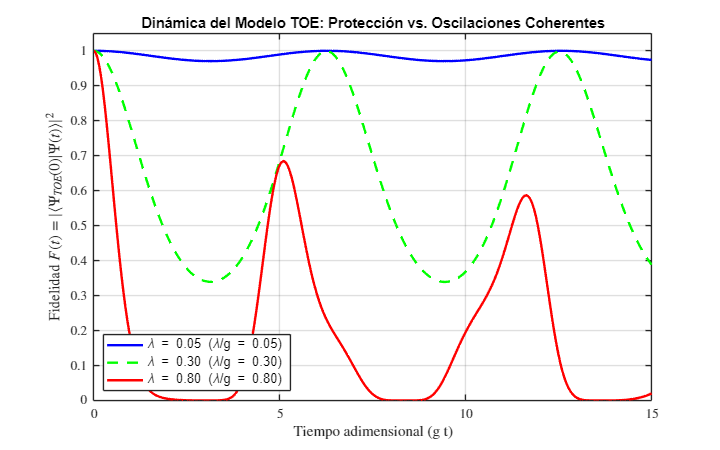

%% 2. OPERADORES BASE (Subespacios individuales)
% Qutrit: Operador cíclico X_hat (x=1, y=2, z=3)
X_q = [0 0 1; 
       1 0 0; 
       0 1 0]; 

% Oscilador: Operadores de aniquilación y creación
a_osc = zeros(dim_osc);
for n = 1:(dim_osc-1)
    a_osc(n, n+1) = sqrt(n);
end
adag_osc = a_osc';
N_osc = adag_osc * a_osc;

% Identidades
I_q = eye(dim_q);
I_osc = eye(dim_osc);
I_single = eye(dim_single);

%% 3. EXTENSIÓN A LAS 3 FUENTES (Espacio de Hilbert total)
% Operadores para cada fuente individual en el espacio total
% Fuente 1
X1 = kron(kron(X_q, I_osc), kron(I_single, I_single));
a1 = kron(kron(I_q, a_osc), kron(I_single, I_single));
adag1 = a1';
N1 = kron(kron(I_q, N_osc), kron(I_single, I_single));

% Fuente 2
X2 = kron(kron(I_single, kron(X_q, I_osc)), I_single);
a2 = kron(kron(I_single, kron(I_q, a_osc)), I_single);
adag2 = a2';
N2 = kron(kron(I_single, kron(I_q, N_osc)), I_single);

% Fuente 3
X3 = kron(I_single, kron(I_single, kron(X_q, I_osc)));
a3 = kron(I_single, kron(I_single, kron(I_q, a_osc)));
adag3 = a3';
N3 = kron(I_single, kron(I_single, kron(I_q, N_osc)));

%% 4. HAMILTONIANO INDEPENDIENTE DEL ACOPLAMIENTO (H_0 y H_int^dir)
% Hamiltoniano libre de los osciladores
H0 = hbar*w1*(N1 + 0.5*eye(dim_total)) + ...
     hbar*w2*(N2 + 0.5*eye(dim_total)) + ...
     hbar*w3*(N3 + 0.5*eye(dim_total));

% Hamiltoniano de interacción direccional entre qutrits
H_dir = (hbar * g / 2) * (X1*X2*X3 + X1'*X2'*X3');

%% 5. ESTADO INICIAL |Psi_TOE> x |0,0,0>
% Qutrits: 1/sqrt(3) * (|xyz> + |yzx> + |zxy>) -> |1,2,3>, |2,3,1>, |3,1,2>
psi_dir = zeros(dim_q^3, 1);
idx_xyz = (1-1)*9 + (2-1)*3 + 3; % |x,y,z>
idx_yzx = (2-1)*9 + (3-1)*3 + 1; % |y,z,x>
idx_zxy = (3-1)*9 + (1-1)*3 + 2; % |z,x,y>

psi_dir(idx_xyz) = 1/sqrt(3);
psi_dir(idx_yzx) = 1/sqrt(3);
psi_dir(idx_zxy) = 1/sqrt(3);

% Vacío vibracional |0,0,0>
vac_osc = zeros(dim_osc^3, 1);
vac_osc(1) = 1; % Estado |0> para los tres osciladores

% Reordenamiento al espacio entrelazado (Fuente 1 x Fuente 2 x Fuente 3)
% Teniendo en cuenta la estructura (q1 x osc1) x (q2 x osc2) x (q3 x osc3)
psi_0 = zeros(dim_total, 1);
% Construcción explícita del kets inicial
v_x = [1;0;0]; v_y = [0;1;0]; v_z = [0;0;1];
v_0 = zeros(dim_osc, 1); v_0(1) = 1;

ket_xyz0 = kron(kron(kron(v_x,v_0), kron(v_y,v_0)), kron(v_z,v_0));
ket_yzx0 = kron(kron(kron(v_y,v_0), kron(v_z,v_0)), kron(v_x,v_0));
ket_zxy0 = kron(kron(kron(v_z,v_0), kron(v_x,v_0)), kron(v_y,v_0));

psi_0 = (1/sqrt(3)) * (ket_xyz0 + ket_yzx0 + ket_zxy0);

%% 6. SIMULACIÓN TEMPORAL PARA DISTINTOS ACOPLAMIENTOS (lambda)
t = linspace(0, 15, 300); % Malla de tiempo
lambdas = [0.05, 0.3, 0.8]; % Débil, intermedio, fuerte
color_lines = {'b-', 'g--', 'r-'};

figure('Color', [1 1 1], 'Position', [100 100 800 500]);
hold on; grid on; box on;

for k = 1:length(lambdas)
    lambda = lambdas(k);
    
    % Hamiltoniano oscilador-dirección
    H_osc_dir = hbar * lambda * (X1*adag1 + X1'*a1 + ...
                                 X2*adag2 + X2'*a2 + ...
                                 X3*adag3 + X3'*a3);
                             
    % Hamiltoniano Total
    H_total = H0 + H_dir + H_osc_dir;
    
    % Diagonalización para la evolución temporal: H = V * D * V'
    [V, D] = eig(H_total);
    diag_D = diag(D);
    
    % Proyección del estado inicial en la base propia
    c = V' * psi_0;
    
    % Fidelidad F(t) = |<psi_0|psi(t)>|^2
    F = zeros(size(t));
    for it = 1:length(t)
        psi_t = V * (c .* exp(-1i * diag_D * t(it) / hbar));
        F(it) = abs(psi_0' * psi_t)^2;
    end
    
    plot(t, F, color_lines{k}, 'LineWidth', 2, ...
        'DisplayName', sprintf('\\lambda = %.2f (\\lambda/g = %.2f)', lambda, lambda/g));
end

% Ajustes estéticos de la gráfica para publicación
xlabel('Tiempo adimensional (g t)', 'FontSize', 12, 'Interpreter', 'latex');
ylabel('Fidelidad $F(t) = |\langle \Psi_{TOE}(0) | \Psi(t) \rangle|^2$', 'FontSize', 12, 'Interpreter', 'latex');
title('Dinámica del Modelo TOE: Protección vs. Oscilaciones Coherentes', 'FontSize', 14);
ylim([0 1.05]);
legend('Location', 'southwest', 'FontSize', 11);
set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11);

%% 7. ANÁLISIS DE LA FRECUENCIA DE RABI
% Verificación numérica de Omega_Rabi = sqrt(g^2 + (2*lambda)^2)
lambda_test = 0.8;
Omega_teorico = sqrt(g^2 + (2*lambda_test)^2);
fprintf('\n--- Verificación Teórica ---');


--- Verificación Teórica ---

fprintf('\nPara lambda = %.2f, g = %.2f:', lambda_test, g);


Para lambda = 0.80, g = 1.00:

fprintf('\nFrecuencia teórica de Rabi (efectiva): %.4f rad/s\n', Omega_teorico);


Frecuencia teórica de Rabi (efectiva): 1.8868 rad/s


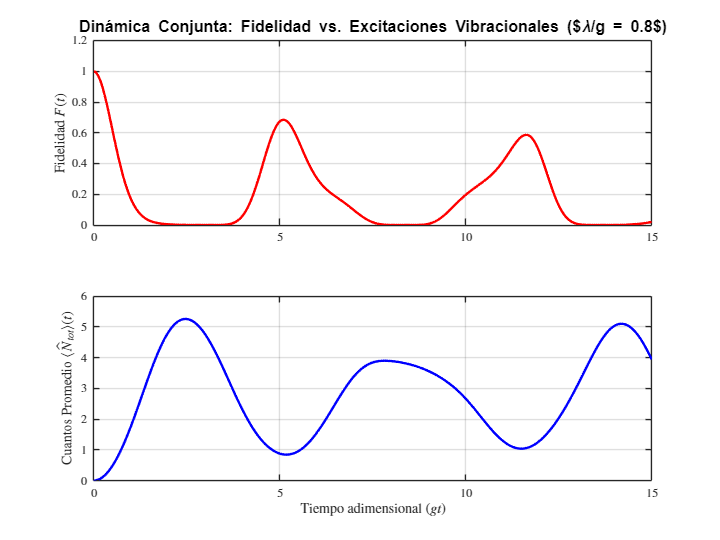


%% MUESTRA DE POBLACIÓN DE CUANTOS <N(t)> Y FIDELIDAD
% Añadir dentro del bucle de simulación temporal:

% Operador número total de cuantos: N_total = N1 + N2 + N3
N_tot = N1 + N2 + N3;

% En el bucle temporal it:
N_avg = zeros(size(t));
for it = 1:length(t)
    psi_t = V * (c .* exp(-1i * diag_D * t(it) / hbar));
    F(it) = abs(psi_0' * psi_t)^2;
    N_avg(it) = real(psi_t' * N_tot * psi_t); % Cuantos promedio totales
end

% Gráfica comparativa de 2 paneles
figure('Color', [1 1 1], 'Position', [100 100 800 600]);

subplot(2,1,1);
plot(t, F, 'r-', 'LineWidth', 2);
ylabel('Fidelidad $F(t)$', 'Interpreter', 'latex', 'FontSize', 12);
title('Dinámica Conjunta: Fidelidad vs. Excitaciones Vibracionales ($\lambda/g = 0.8$)', 'FontSize', 13);
grid on; set(gca, 'TickLabelInterpreter', 'latex');

subplot(2,1,2);
plot(t, N_avg, 'b-', 'LineWidth', 2);
xlabel('Tiempo adimensional ($g t$)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Cuantos Promedio $\langle \hat{N}_{tot} \rangle(t)$', 'Interpreter', 'latex', 'FontSize', 12);
grid on; set(gca, 'TickLabelInterpreter', 'latex');

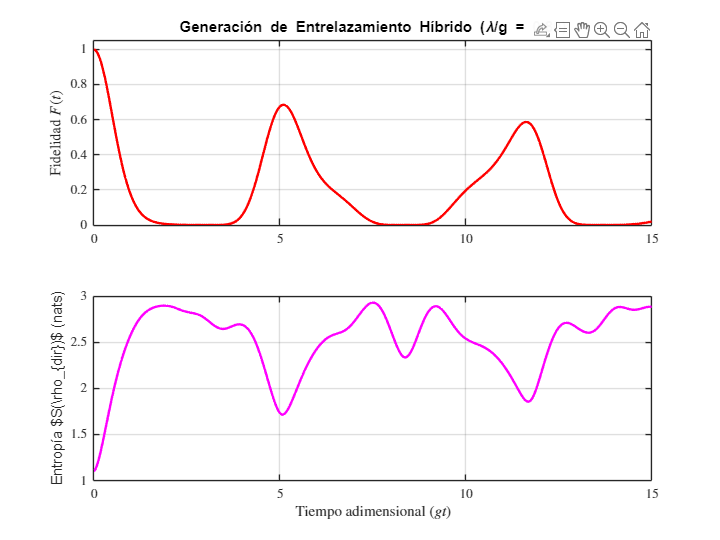

%% MODELO TOE - CÁLCULO DE ENTROPÍA DE VON NEUMANN S(rho_dir)
% Autor: Kilian Hernández Cabrera
% Simulación del Entrelazamiento Híbrido (Qutrits - Osciladores)

clear; clc; close all;

%% 1. PARÁMETROS DEL SISTEMA
hbar = 1; g = 1.0; lambda = 0.8; % Régimen de acoplamiento fuerte
w1 = 1.0; w2 = 1.0; w3 = 1.0;
n_max = 3; 

dim_q = 3; dim_osc = n_max + 1;
dim_q_tot = dim_q^3;       % Dimensión subespacio direcciones (27)
dim_osc_tot = dim_osc^3;   % Dimensión subespacio osciladores (64)
dim_total = dim_q_tot * dim_osc_tot; % 1728

%% 2. OPERADORES BASE
X_q = [0 0 1; 1 0 0; 0 1 0];
a_osc = zeros(dim_osc);
for n = 1:(dim_osc-1), a_osc(n, n+1) = sqrt(n); end
adag_osc = a_osc'; N_osc = adag_osc * a_osc;

I_q = eye(dim_q); I_osc = eye(dim_osc); I_single = eye(dim_q*dim_osc);

%% 3. EXTENSIÓN AL ESPACIO TOTAL
% (Mantenemos la descomposición limpia)
X1 = kron(kron(X_q, I_osc), kron(I_single, I_single));
a1 = kron(kron(I_q, a_osc), kron(I_single, I_single)); adag1 = a1';
N1 = kron(kron(I_q, N_osc), kron(I_single, I_single));

X2 = kron(kron(I_single, kron(X_q, I_osc)), I_single);
a2 = kron(kron(I_single, kron(I_q, a_osc)), I_single); adag2 = a2';
N2 = kron(kron(I_single, kron(I_q, N_osc)), I_single);

X3 = kron(I_single, kron(I_single, kron(X_q, I_osc)));
a3 = kron(I_single, kron(I_single, kron(I_q, a_osc))); adag3 = a3';
N3 = kron(I_single, kron(I_single, kron(I_q, N_osc)));

H0 = hbar*w1*(N1 + 0.5*eye(dim_total)) + ...
     hbar*w2*(N2 + 0.5*eye(dim_total)) + ...
     hbar*w3*(N3 + 0.5*eye(dim_total));
H_dir = (hbar * g / 2) * (X1*X2*X3 + X1'*X2'*X3');
H_osc_dir = hbar * lambda * (X1*adag1 + X1'*a1 + X2*adag2 + X2'*a2 + X3*adag3 + X3'*a3);

H_total = H0 + H_dir + H_osc_dir;

%% 4. ESTADO INICIAL |Psi_0>
v_x = [1;0;0]; v_y = [0;1;0]; v_z = [0;0;1];
v_0 = zeros(dim_osc, 1); v_0(1) = 1;

ket_xyz0 = kron(kron(kron(v_x,v_0), kron(v_y,v_0)), kron(v_z,v_0));
ket_yzx0 = kron(kron(kron(v_y,v_0), kron(v_z,v_0)), kron(v_x,v_0));
ket_zxy0 = kron(kron(kron(v_z,v_0), kron(v_x,v_0)), kron(v_y,v_0));

psi_0 = (1/sqrt(3)) * (ket_xyz0 + ket_yzx0 + ket_zxy0);

%% 5. EVOLUCIÓN TEMPORAL Y TRAZA PARCIAL
t = linspace(0, 15, 300);
[V, D] = eig(H_total);
diag_D = diag(D);
c = V' * psi_0;

F = zeros(size(t));
S_dir = zeros(size(t));

for it = 1:length(t)
    % Estado en el instante t
    psi_t = V * (c .* exp(-1i * diag_D * t(it) / hbar));
    
    % Fidelidad
    F(it) = abs(psi_0' * psi_t)^2;
    
    % Reorganizar el vector ket psi_t en una matriz de dimensión (dim_q_tot x dim_osc_tot)
    % para realizar la Traza Parcial trazando los osciladores rápidamente:
    % rho_dir = Psi * Psi'
    Psi_mat = reshape(psi_t, [dim_osc_tot, dim_q_tot]).'; % Transpuesta para dejar dim_q_tot
    rho_dir = Psi_mat * (Psi_mat'); % Traza parcial sobre el subespacio oscilatorio
    
    % Autovalores de rho_dir para calcular Entropía de Von Neumann
    eig_rho = real(eig(rho_dir));
    eig_rho = eig_rho(eig_rho > 1e-12); % Filtro numérico para evitar log(0)
    
    % S(rho) = - sum( p_i * log(p_i) )
    S_dir(it) = -sum(eig_rho .* log(eig_rho)); 
end

%% 6. GRAFICAR RESULTADOS EN 2 PANELES
figure('Color', [1 1 1], 'Position', [100 100 800 600]);

% Panel Superior: Fidelidad
subplot(2,1,1);
plot(t, F, 'r-', 'LineWidth', 2);
ylabel('Fidelidad $F(t)$', 'Interpreter', 'latex', 'FontSize', 12);
title(sprintf('Generación de Entrelazamiento Híbrido (\\lambda/g = %.2f)', lambda/g), 'FontSize', 14);
grid on; set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11);
ylim([0 1.05]);

% Panel Inferior: Entropía de Von Neumann
subplot(2,1,2);
plot(t, S_dir, 'm-', 'LineWidth', 2);
xlabel('Tiempo adimensional ($g t$)', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Entropía $S(\rho_{dir})$ (nats)', 'Interpreter', 'latex', 'FontSize', 12);
grid on; set(gca, 'TickLabelInterpreter', 'latex', 'FontSize', 11);

% Anotación en la gráfica
text(2, 0.2, '\leftarrow Estado Puro (S=0)', 'FontSize', 10, 'Interpreter', 'latex');

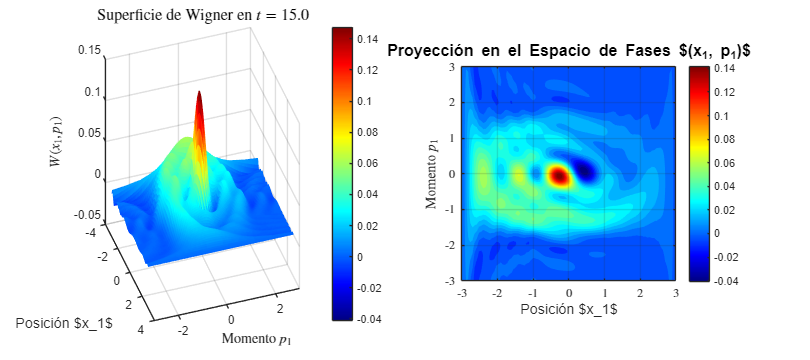

%% MODELO TOE - FUNCIÓN DE WIGNER EN EL ESPACIO DE FASES W(x,p)
% Reconstrucción del estado vibracional de la Fuente 1

clear; clc; close all;

%% 1. PARÁMETROS DEL SISTEMA
hbar = 1; g = 1.0; lambda = 0.8; % Régimen de acoplamiento fuerte
w1 = 1.0; w2 = 1.0; w3 = 1.0;
n_max = 5; % Elevamos un poco n_max para mejor resolución espacial (0..5)

dim_q = 3; dim_osc = n_max + 1;
dim_single = dim_q * dim_osc;
dim_total = dim_single^3;

%% 2. OPERADORES BASE
X_q = [0 0 1; 1 0 0; 0 1 0];
a_osc = zeros(dim_osc);
for n = 1:(dim_osc-1), a_osc(n, n+1) = sqrt(n); end
adag_osc = a_osc'; N_osc = adag_osc * a_osc;

I_q = eye(dim_q); I_osc = eye(dim_osc); I_single = eye(dim_single);

%% 3. EXTENSIÓN AL ESPACIO TOTAL
X1 = kron(kron(X_q, I_osc), kron(I_single, I_single));
a1 = kron(kron(I_q, a_osc), kron(I_single, I_single)); adag1 = a1';
N1 = kron(kron(I_q, N_osc), kron(I_single, I_single));

X2 = kron(kron(I_single, kron(X_q, I_osc)), I_single);
a2 = kron(kron(I_single, kron(I_q, a_osc)), I_single); adag2 = a2';
N2 = kron(kron(I_single, kron(I_q, N_osc)), I_single);

X3 = kron(I_single, kron(I_single, kron(X_q, I_osc)));
a3 = kron(I_single, kron(I_single, kron(I_q, a_osc))); adag3 = a3';
N3 = kron(I_single, kron(I_single, kron(I_q, N_osc)));

H0 = hbar*w1*(N1 + 0.5*eye(dim_total)) + ...
     hbar*w2*(N2 + 0.5*eye(dim_total)) + ...
     hbar*w3*(N3 + 0.5*eye(dim_total));
H_dir = (hbar * g / 2) * (X1*X2*X3 + X1'*X2'*X3');
H_osc_dir = hbar * lambda * (X1*adag1 + X1'*a1 + X2*adag2 + X2'*a2 + X3*adag3 + X3'*a3);

H_total = H0 + H_dir + H_osc_dir;

%% 4. ESTADO INICIAL |Psi_0>
v_x = [1;0;0]; v_y = [0;1;0]; v_z = [0;0;1];
v_0 = zeros(dim_osc, 1); v_0(1) = 1;

ket_xyz0 = kron(kron(kron(v_x,v_0), kron(v_y,v_0)), kron(v_z,v_0));
ket_yzx0 = kron(kron(kron(v_y,v_0), kron(v_z,v_0)), kron(v_x,v_0));
ket_zxy0 = kron(kron(kron(v_z,v_0), kron(v_x,v_0)), kron(v_y,v_0));

psi_0 = (1/sqrt(3)) * (ket_xyz0 + ket_yzx0 + ket_zxy0);

%% 5. EVOLUCIÓN TEMPORAL

% Instantes para los maximos de fidelidad:
%t_target = 0; 
%t_target = 5;
%t_target = 12.5;
% Instantes para los minimos de fiabilidad (maximos de entropia):
%t_target = 2.5; 
%t_target = 7.5;
t_target = 15;
[V, D] = eig(H_total);
psi_t = V * ((V' * psi_0) .* exp(-1i * diag(D) * t_target / hbar));

%% 6. TRAZA PARCIAL PARA OBTENER rho_osc1 (Matriz densidad del Oscilador 1)
% Reagrupamos índices para trazar (Dirección 1,2,3 y Osciladores 2,3)
% Dejando solo el subespacio del Oscilador 1 (dim_osc x dim_osc)
Psi_tensor = reshape(psi_t, [dim_q, dim_osc, dim_q, dim_osc, dim_q, dim_osc]);
% Permutamos para dejar Oscilador 1 al principio
Psi_perm = permute(Psi_tensor, [2, 1, 3, 4, 5, 6]);
Psi_mat = reshape(Psi_perm, [dim_osc, dim_q^3 * dim_osc^2]);

rho_osc1 = Psi_mat * (Psi_mat'); % Matriz densidad reducida 6x6 del oscilador 1

%% 7. CÁLCULO DE LA FUNCIÓN DE WIGNER W(x, p)
x = linspace(-3, 3, 100);
p = linspace(-3, 3, 100);
[X, P] = meshgrid(x, p);
W = zeros(size(X));

% Base de funciones de onda del oscilador armónico psi_n(x)
psi_n = zeros(dim_osc, length(x));
for n = 0:(dim_osc-1)
    % Polinomio de Hermite
    H_n = hermitePoly(n, x);
    psi_n(n+1, :) = (1/pi^(1/4)) * (1/sqrt(2^n * factorial(n))) .* H_n .* exp(-x.^2 / 2);
end

% Cálculo de Wigner vía integral de solapamiento en x
for ix = 1:length(x)
    for ip = 1:length(p)
        x_val = X(ip, ix);
        p_val = P(ip, ix);
        
        % Integración sobre la coordenada y: <x-y/2| rho |x+y/2> * exp(2i p y)
        y = linspace(-4, 4, 101);
        dy = y(2) - y(1);
        integrand = 0;
        
        for n = 0:(dim_osc-1)
            for m = 0:(dim_osc-1)
                if abs(rho_osc1(n+1, m+1)) > 1e-6
                    psi_m_plus = interp1(x, psi_n(m+1,:), x_val + y/2, 'linear', 0);
                    psi_n_minus = interp1(x, psi_n(n+1,:), x_val - y/2, 'linear', 0);
                    
                    term = rho_osc1(n+1, m+1) * psi_m_plus .* psi_n_minus .* exp(2i * p_val * y);
                    integrand = integrand + sum(term) * dy;
                end
            end
        end
        W(ip, ix) = real(integrand) / (2*pi);
    end
end

%% 8. REPRESENTACIÓN GRÁFICA (SURF 3D Y CONTURNO 2D)
figure('Color', [1 1 1], 'Position', [100 100 900 400]);

% Panel 1: Superficie 3D
subplot(1,2,1);
surf(X, P, W, 'EdgeColor', 'none');
colormap(jet); colorbar; view([-35 45]);
xlabel('Posición $x_1$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Momento $p_1$', 'Interpreter', 'latex', 'FontSize', 12);
zlabel('$W(x_1, p_1)$', 'Interpreter', 'latex', 'FontSize', 12);
title(sprintf('Superficie de Wigner en $t = %.1f$', t_target), 'Interpreter', 'latex', 'FontSize', 13);

% Panel 2: Mapa de Contornos 2D
subplot(1,2,2);
contourf(X, P, W, 30, 'LineColor', 'none');
colormap(jet); colorbar; axis square;
xlabel('Posición $x_1$', 'Interpreter', 'latex', 'FontSize', 12);
ylabel('Momento $p_1$', 'Interpreter', 'latex', 'FontSize', 12);
title('Proyección en el Espacio de Fases $(x_1, p_1)$', 'FontSize', 13);
grid on; set(gca, 'TickLabelInterpreter', 'latex');

%% FUNCIÓN AUXILIAR PARA POLINOMIOS DE HERMITE
function H = hermitePoly(n, x)
    if n == 0
        H = ones(size(x));
    elseif n == 1
        H = 2 * x;
    elseif n == 2
        H = 4 * x.^2 - 2;
    elseif n == 3
        H = 8 * x.^3 - 12 * x;
    elseif n == 4
        H = 16 * x.^4 - 48 * x.^2 + 12;
    elseif n == 5
        H = 32 * x.^5 - 160 * x.^3 + 120 * x;
    end
end